# Electron in Periodic Potential

## References

- Ashcroft, Neil W., and N. David Mermin. "Solid State Physics, College edn." *Thomson Learning Inc* (1976).

- Kittel, Charles, and Paul McEuen. *Introduction to solid state physics*. John Wiley & Sons, 2018.

- [http://lampx.tugraz.at/~hadley/ss1/crystalstructure/crystalstructure.php](http://lampx.tugraz.at/~hadley/ss1/crystalstructure/crystalstructure.php)

## Introduction

Schrödinger Equation (in atomic units)


$$\left\lbrack -\frac{\nabla^2 }{2}+U\left(\mathbf{r}\right)\right\rbrack \psi \left(\mathbf{r}\right)=E\psi \left(\mathbf{r}\right)$$


Periodic potential:


$$U\left(\mathbf{r}\right)=\sum_{\mathbf{G}} U_{\mathbf{G}} e^{i\;\mathbf{G}\cdot \mathbf{r}}$$


with $\mathbf{G}=h{\mathbf{b}}_1 +k{\mathbf{b}}_2 +l{\mathbf{b}}_3$ and $\left\lbrace h,k,l\right\rbrace \in \mathbb{Z}$

Bloch theorem:


$$\psi \left(\mathbf{r}\right)=u\left(\mathbf{r}\right)e^{i\;\mathbf{k}\cdot \mathbf{r}} =\sum_{\mathbf{G}} C_{\mathbf{k}-\mathbf{G}} {\;e}^{i\left(\mathbf{k}-\mathbf{G}\right)\cdot \mathbf{r}}$$


Substitute into SE:


$$\frac{{\left|\mathbf{k}-\mathbf{G}\right|}^2 }{2}C_{\mathbf{k}-\mathbf{G}} +\sum_{\mathbf{G}\prime } U_{\mathbf{G}\prime -\mathbf{G}} C_{\mathbf{k}-\mathbf{G}\prime } =E\;C_{\mathbf{k}-\mathbf{G}}$$


or as an eigenvalue problem


$$\underline{\underline{\mathrm{A}} } \;\mathbf{C}=E\;\mathbf{C}$$



$$\underline{\underline{\mathrm{A}} } =\frac{1}{2}\textrm{diag}\left\lbrack \begin{array}{c}
{\left|\mathbf{k}-{\mathbf{G}}_1 \right|}^2 \\
{\left|\mathbf{k}-{\mathbf{G}}_2 \right|}^2 \\
{\left|\mathbf{k}-{\mathbf{G}}_3 \right|}^2 \\
\vdots 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cccc}
U_0  & U_{{\mathbf{G}}_2 -{\mathbf{G}}_1 }  & U_{{\mathbf{G}}_3 -{\mathbf{G}}_1 }  & \cdots \\
U_{{\mathbf{G}}_1 -{\mathbf{G}}_2 }  & U_0  & U_{{\mathbf{G}}_3 -{\mathbf{G}}_2 }  & \cdots \\
U_{{\mathbf{G}}_1 -{\mathbf{G}}_3 }  & U_{{\mathbf{G}}_2 -{\mathbf{G}}_3 }  & U_0  & \cdots \\
\vdots  & \vdots  & \vdots  & \ddots 
\end{array}\right\rbrack$$


For simplicity, set $U_0 =0$

Assuming a Coulomb-like potential $U\left(\mathbf{r}\right)=-\sum_{\mathbf{R}} \left|\frac{\alpha }{\mathbf{r}-\mathbf{R}}\right|$ gives


$$U_{\mathbf{G}} =-\frac{\beta }{h^2 +k^2 +l^2 }$$


### Procedure:

- Define $\mathbf{k}=\sum_n a_n {\mathbf{b}}_n \;$ where $\left\lbrace a_n :a_n \in \mathbb{R},\left|a_n \right|\le 1\right\rbrace$

- Define ${\mathbf{G}}_{\max } =\sum_n g_{\max } {\mathbf{b}}_n$ where $\left\lbrace g_{\max } :g_{\max } \in {\mathbb{N}}^+ \right\rbrace$

- Generate all vectors $\mathbf{G}=\sum_n g_n {\mathbf{b}}_n$ where$\left\lbrace g_n :g_n \in \mathbb{Z},\left|g_n \right|\le g_{\max } \right\rbrace$(i.e. ${\left|\mathbf{G}\right|}^2 \le {\left|{\mathbf{G}}_{\max } \right|}^2$)

- Create matrix $\underline{\underline{\mathrm{A}} }$

- Solve eigenvalue problem for $\mathbf{C}$ and $E$

## Initialisation

clear
Proj = currentProject;

MASK = @(A, M, val) subsasgn(A, struct("type", "()", "subs", {{M}}), val); %#ok<SUBSASGN> 
VECTOR = @(A, dim) reshape(A, [ones(1, dim-1) numel(A) 1]);

NG = 5;
NG1 = 2*NG+1;
Nk = 25;
nG = (-NG:NG).';

## 1D

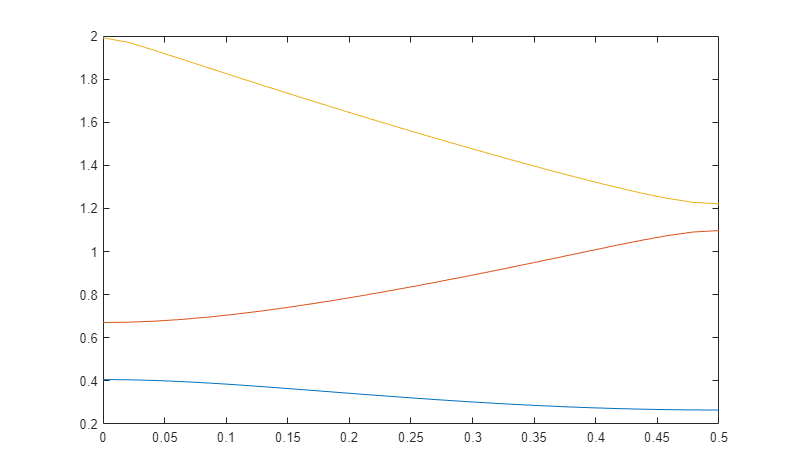

Nk1 = Nk;
k1 = .5*linspace(0, 1, Nk).';
U01 = .25;

E1 = zeros(Nk, NG1);
U1 = U01./(Row(nG)-Column(nG)).^2;
U1(~isfinite(U1)) = 0;
for nk=1:Nk1
	[~, D] = eig(diag(.5*(k1(nk)-nG).^2) + U1);
	E1(nk, :) = diag(D);
end

Figure;
plot(k1, E1(:, 2:4))

## 2D

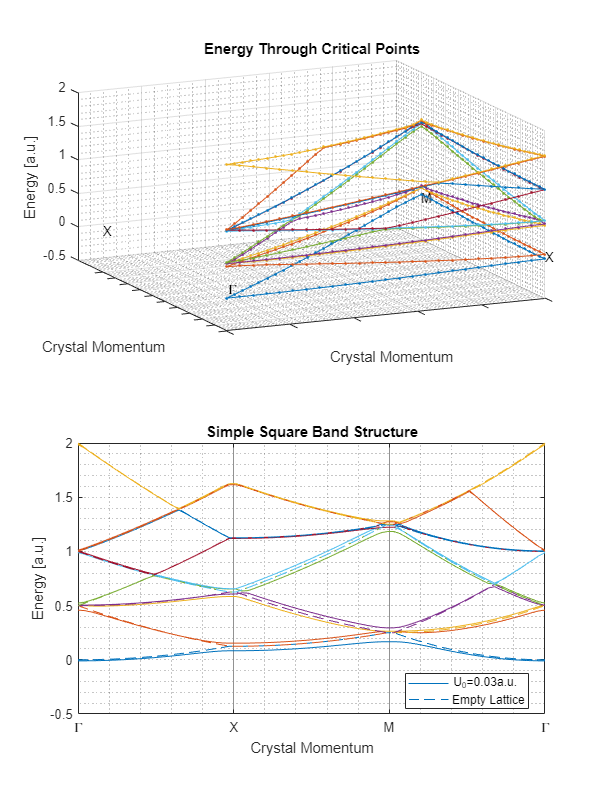

NG2 = NG1^2;
N2 = 3;
Nk2 = N2*Nk;
U02 = .03;

%	Wave vector goes from gamma to X to M to Gamma
k2 = .5*[ ...
	[linspace(0, 1, Nk).'; ones(Nk, 1); 1-linspace(0, 1, Nk).'] ...
	[zeros(Nk, 1); linspace(0, 1, Nk).'; 1-linspace(0, 1, Nk).']];

%	G = n1*b1 + n2*b2 with integer n1, n2
G2 = [Column(repmat(Column(nG), [1 NG1])) ...
	Column(repmat(Row(nG), [NG1 1]))];

U2 = -U02./sum((reshape(G2, 1, [], 2)-reshape(G2, [], 1, 2)).^2, 3);
U2(~isfinite(U2)) = 0;

E2 = zeros(Nk2, NG2);
E2_empty = E2;
for nk=1:Nk2
	[~, D] = eig(diag(.5*sum((k2(nk, :)-G2).^2, 2)) + U2);
	E2(nk, :) = diag(D);

	[~, D] = eig(diag(.5*sum((k2(nk, :)-G2).^2, 2)));
	E2_empty(nk, :) = diag(D);
end

indE = 1:10;
Emn = min(E2(:, indE), [], "all");

fig = Figure(Width=750, Height=1000);
T = tiledlayout(fig, "Flow");

ax = nexttile(T);
plot3(ax, k2(:, 1), k2(:, 2), E2(:, indE), ".-");
grid on;
grid minor;
xticklabels([]);
yticklabels([]);
text(0, 0, Emn, "\Gamma", "VerticalAlignment", "Bottom");
text(.5, 0, Emn, "X", "VerticalAlignment", "Bottom");
text(.5, .5, Emn, "M", "VerticalAlignment", "Bottom");
text(0, .5, Emn, "X", "VerticalAlignment", "Bottom");
view(-25, 25);
title("Energy Through Critical Points");
xlabel("Crystal Momentum")
ylabel("Crystal Momentum")
zlabel("Energy [a.u.]")

ax = nexttile(T);
h1 = plot(ax, linspace(0, N2, Nk2).', E2(:, indE), "-");
h2 = line(ax, linspace(0, N2, Nk2).', E2_empty(:, indE), ...
	"LineStyle", "--");
xticks(0:N2);
xticklabels(["\Gamma" "X" "M" "\Gamma"]);
ax.GridAlpha = .5;
ax.XGrid = "On";
grid minor;
title("Simple Square Band Structure");
ylabel("Energy [a.u.]");
xlabel("Crystal Momentum")
legend([h1(1) h2(1)], ...
	["U_0="+U02+"a.u." "Empty Lattice"], ...
	"Location", "Best");

## 3D

### Simple Cubic (SC)

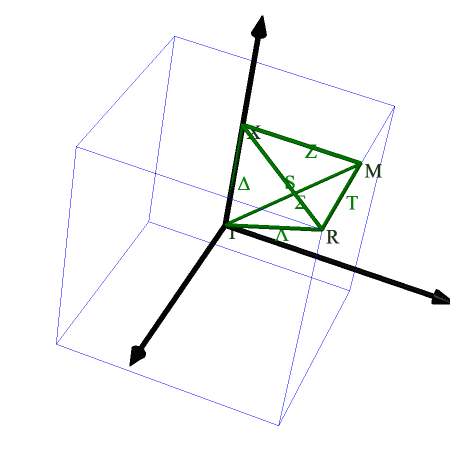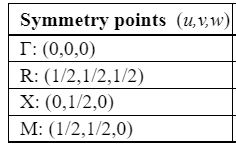

### Face-Centred Cubic (FCC)

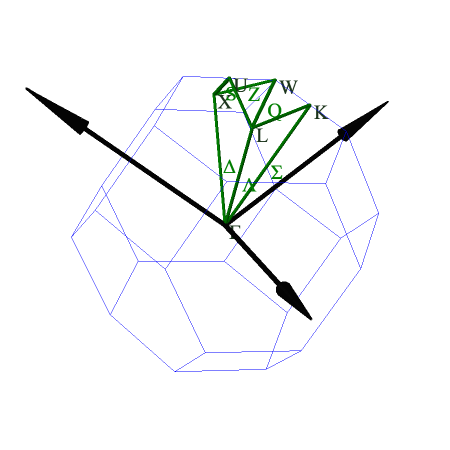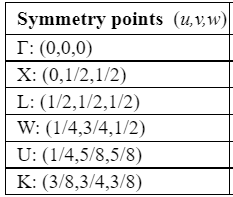

### Body-Centred Cubic (BCC)

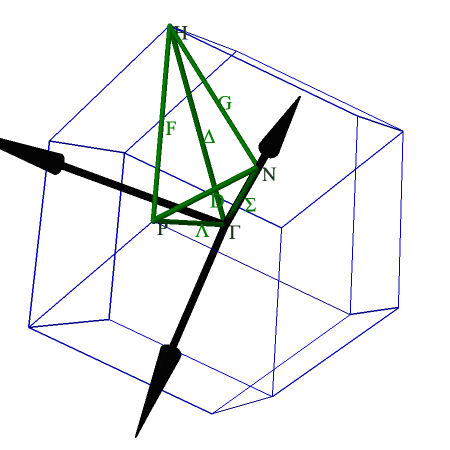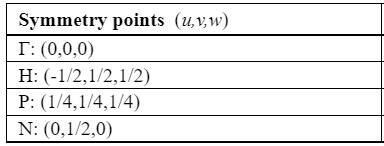

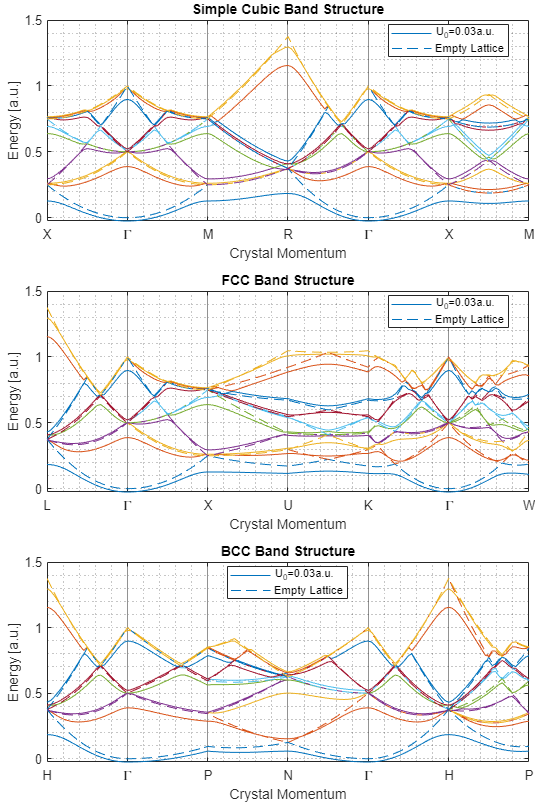

NG3 = NG1^3;
N3 = 6;
Nk3 = N3*(Nk-1)+1;
U03 = .03;

V = @(v1, v2) [linspace(v1(1), v2(1), Nk).' linspace(v1(2), v2(2), Nk).' linspace(v1(3), v2(3), Nk).'];
VSUBS = @(V) V([true; any(logical(diff(V)), 2)], :);

G = [0 0 0];	%	G = gamma point
X = [0 1 1]/2;

%	Simple cubic: X G M R G X M
M = [1 1 0]/2;
R = [1 1 1]/2;
k3_SC = VSUBS([V(X, G); V(G, M); V(M, R); V(R, G); V(G, X); V(X, M)]);

%	FCC: L G X U K G W
L = [1 1 1]/2;
W = [1 3 2]/4;
U = [2 5 5]/8;
K = [3 6 3]/8;
k3_FCC = VSUBS([V(L, G); V(G, X); V(X, U); V(U, K); V(K, G); V(G, W)]);

%	BCC: H G P N G H P
H = [-1 1 1]/2;	
P = [1 1 1]/4;
N = [0 1 0]/2;
k3_BCC = VSUBS([V(H, G); V(G, P); V(P, N); V(N, G); V(G, H); V(H, P)]);

%	G = n1*b1 + n2*b2 with integer n1, n2
G3 = [Column(repmat(Column(nG), [1 NG1 NG1])) ...
	Column(repmat(Row(nG), [NG1 1 NG1])) ...
	Column(repmat(Page(nG), [NG1 NG1 1]))];

U3 = -U03./sum((reshape(G3, 1, [], 3)-reshape(G3, [], 1, 3)).^2, 3);
U3(~isfinite(U3)) = 0;

E3_SC = zeros(Nk3, NG3);
E3_FCC = E3_SC;
E3_BCC = E3_SC;
E3_SCEmpty = E3_SC;
E3_FCCEmpty = E3_SC;
E3_BCCEmpty = E3_SC;
for nk=1:Nk3
	%	SC
	[~, D] = eig(diag(.5*sum((k3_SC(nk, :)-G3).^2, 2)) + U3);
	E3_SC(nk, :) = diag(D);

	[~, D] = eig(diag(.5*sum((k3_SC(nk, :)-G3).^2, 2)));
	E3_SCEmpty(nk, :) = diag(D);

	%	FCC
	[~, D] = eig(diag(.5*sum((k3_FCC(nk, :)-G3).^2, 2)) + U3);
	E3_FCC(nk, :) = diag(D);

	[~, D] = eig(diag(.5*sum((k3_FCC(nk, :)-G3).^2, 2)));
	E3_FCCEmpty(nk, :) = diag(D);

	%	BCC
	[~, D] = eig(diag(.5*sum((k3_BCC(nk, :)-G3).^2, 2)) + U3);
	E3_BCC(nk, :) = diag(D);

	[~, D] = eig(diag(.5*sum((k3_BCC(nk, :)-G3).^2, 2)));
	E3_BCCEmpty(nk, :) = diag(D);
end

indE = 1:10;
Emn = min(E3_SC(:, indE), [], "all");

fig = Figure(Height=1200, Width=800);
T = tiledlayout(fig, 3, 1, "Padding", "Tight");

ax = nexttile(T);
h1 = plot(ax, linspace(0, N3, Nk3).', E3_SC(:, indE), "-");
h2 = line(ax, linspace(0, N3, Nk3).', E3_SCEmpty(:, indE), ...
	"LineStyle", "--");
xticks(0:N3);
xticklabels(["X" "\Gamma" "M" "R" "\Gamma" "X" "M"]);
ax.GridAlpha = .5;
ax.XGrid = "On";
grid minor;
title("Simple Cubic Band Structure");
ylabel("Energy [a.u.]");
xlabel("Crystal Momentum")
legend([h1(1) h2(1)], ...
	["U_0="+U03+"a.u." "Empty Lattice"], ...
	"Location", "Best");

ax = nexttile(T);
h1 = plot(ax, linspace(0, N3, Nk3).', E3_FCC(:, indE), "-");
h2 = line(ax, linspace(0, N3, Nk3).', E3_FCCEmpty(:, indE), ...
	"LineStyle", "--");
xticks(0:N3);
xticklabels(["L" "\Gamma" "X" "U" "K" "\Gamma" "W"]);
ax.GridAlpha = .5;
ax.XGrid = "On";
grid minor;
title("FCC Band Structure");
ylabel("Energy [a.u.]");
xlabel("Crystal Momentum")
legend([h1(1) h2(1)], ...
	["U_0="+U03+"a.u." "Empty Lattice"], ...
	"Location", "Best");

ax = nexttile(T);
h1 = plot(ax, linspace(0, N3, Nk3).', E3_BCC(:, indE), "-");
h2 = line(ax, linspace(0, N3, Nk3).', E3_BCCEmpty(:, indE), ...
	"LineStyle", "--");
xticks(0:N3);
xticklabels(["H" "\Gamma" "P" "N" "\Gamma" "H" "P"]);
ax.GridAlpha = .5;
ax.XGrid = "On";
grid minor;
title("BCC Band Structure");
ylabel("Energy [a.u.]");
xlabel("Crystal Momentum")
legend([h1(1) h2(1)], ...
	["U_0="+U03+"a.u." "Empty Lattice"], ...
	"Location", "Best");

## Functions

function fig = Figure(Arg)
%	Returns handle to figure window, clears figure and sets its size & units.
arguments
	Arg.Fig = gcf;
	Arg.Width = 1000;
	Arg.Height = 600;
	Arg.Units = "Pixels";
end
fig = Arg.Fig;
clf(fig);
fig.Units = Arg.Units;
fig.Position = [10 50 Arg.Width Arg.Height];
colormap(fig, "turbo");
end
